
GIm = readmatrix("sub_region_matrix.xlsx");
numofpixels=size(GIm,1)*size(GIm,2);

HIm=uint8(zeros(size(GIm,1),size(GIm,2)));

freq=zeros(79,1);
probf=zeros(36,1);
probc=zeros(36,1);
cum=zeros(36,1);
output=zeros(36,1);
q=zeros(36,1);
rq=zeros(37,1);


for i=1:size(GIm,1)
    for j=1:size(GIm,2)
        value=GIm(i,j);
        freq(value+1)=freq(value+1)+1;
        probf(value+1)=freq(value+1)/numofpixels;
    end
end


sum=0;
no_bins=35;

for i=1:size(probf)
   sum=sum+freq(i);
   cum(i)=sum;
   q(i)=((2^8 -1)/48)*cum(i);
   probc(i)=cum(i)/numofpixels;
   rq(i)=round(q(i));

end



figure('Position',get(0,'screensize'));
dat=cell(36,5);

for i=1:36
dat(i,:)={i+42,freq(i+43),probc(i+43)*48,q(i+43),rq(i+43)};   
end


columnname =   {'Gray-level', '# of Pixels','CDF','qk','round(qk)'};
columnformat = {'numeric', 'numeric', 'numeric', 'numeric','numeric'};
columneditable =  [false false false false false];

t = uitable('Units','normalized','Position',[0.1 0.1 0.4 0.9],'Data', dat,'ColumnName', columnname,'ColumnFormat', columnformat,'ColumnEditable', columneditable,'RowName',[]); 

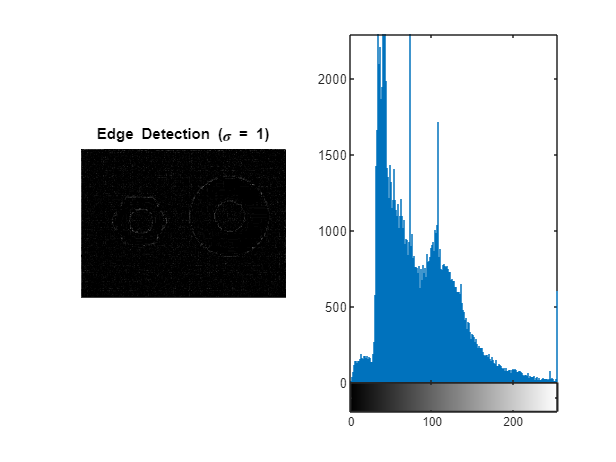


I = imread('Posture_MRI.png');
J =histeq(I);

imshowpair(I,J,'montage')

imhist(I)

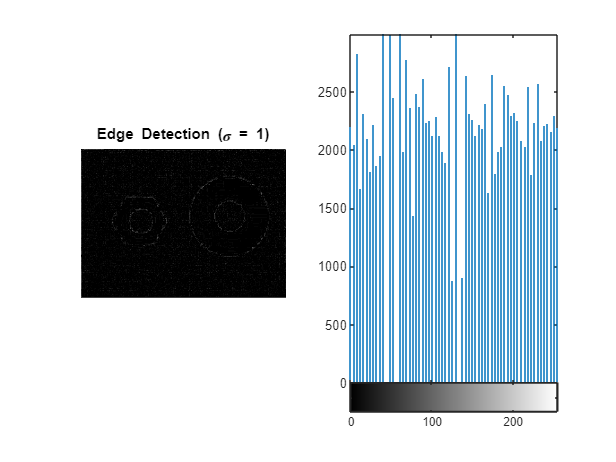

imhist(J)

Sobel_x = [-1 0 1; -2 0 2; -1 0 1];
Sobel_y = [-1 -2 -1; 0 0 0; 1 2 1];

region = [53 48 49; 51 46 48; 48 44 47];

Gx = conv2(region, Sobel_x, 'same');
Gy = conv2(region, Sobel_y, 'same');

gradient_direction = atan2d(Gy(2,2), Gx(2,2))

Im = imread('checker.png');

Hx = [-1 0 1; -2 0 2; -1 0 1];
Hy = [-1 -2 -1; 0 0 0; 1 2 1];
Gx = conv2(Im, Hx, 'same');


Gy = conv2(Im, Hy, 'same');

G = sqrt(Gx(2,2)^2 + Gy(2,2)^2);
% Display the gradient images (Gx, Gy, G)
figure;

subplot(1, 3, 1);
imshow(uint8(Gx), []);
title('Gradient in X direction');

subplot(1, 3, 2);
imshow(uint8(Gy), []);
title('Gradient in Y direction');

subplot(1, 3, 3);
imshow(uint8(G), []);
title('Magnitude of Gradient');


% Compute the gradient using MATLAB functions edge and imgradientxy
[E, T] = edge(Im, 'sobel');
[Gx_MATLAB, Gy_MATLAB] = imgradientxy(Im);
[mag, f] = imgradient(Im);
% Compare the results
figure;

subplot(1, 3, 3);
imshow(E);
title('Edge Detection (MATLAB edge)');

subplot(1, 3, 1);
imshow(uint8(Gx_MATLAB), []);
title('Gradient in X direction (MATLAB imgradientxy)');

subplot(1, 3, 2);
imshow(uint8(Gy_MATLAB), []);
title('Gradient in Y direction (MATLAB imgradientxy)');


% Define the range of x and y values
x = linspace(-5, 5, 100);  % Range from -5 to 5 with 100 points
y = linspace(-5, 5, 100);
[X, Y] = meshgrid(x, y);

% Define sigma values
sigma_values = [1, 3, 5];

% Initialize a figure
figure;

% Loop through each sigma value and plot the Gaussian function
for sigma = sigma_values
    % Compute the Gaussian function
    G = exp(-(X.^2 + Y.^2) / (2 * sigma^2)) / (2 * pi * sigma^2);

    % Create a subplot for each sigma
    subplot(1, 3, find(sigma_values == sigma));
    surf(X, Y, G);
    title(['\sigma = ', num2str(sigma)]);
    xlabel('x');
    ylabel('y');
    zlabel('G(x, y)');
end

% Adjust the layout of the subplots
sgtitle('Gaussian Function for Different \sigma Values');


figure(1)
    % Read the input image
image = imread('Texture.png');

image_gray = rgb2gray(image);


% Define sigma values
sigma_values = [1, 3, 5];

% Initialize a figure to display the results
figure;

% Loop through each sigma value and perform Gaussian smoothing
for i = 1:length(sigma_values)
    sigma = sigma_values(i);
    
    smoothed_image = imgaussfilt(image_gray,sigma,FilterSize=3*sigma);

    % Display the smoothed image
    subplot(1, length(sigma_values), i);
    imshow(smoothed_image);
    title(['\sigma = ', num2str(sigma)]);
end

% Add a title to the entire figure
sgtitle('Gaussian Smoothing with Different \sigma Values');
    

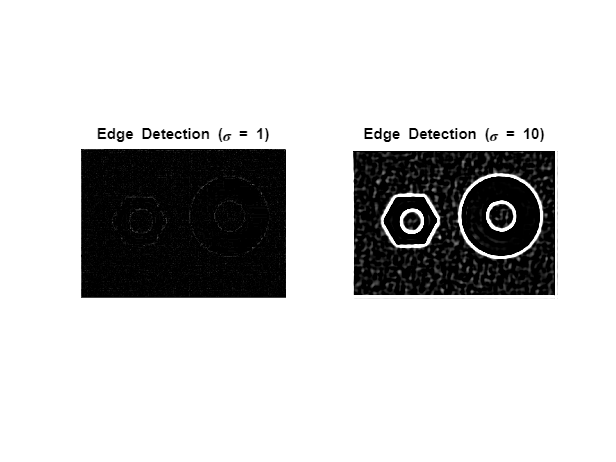

% Read the input image
image = imread('nut_and_shell.png');
% Convert the image to grayscale if it's not already in grayscale
image_gray = rgb2gray(image);


% Define sigma values
sigma1 = 1;
sigma2 = 10;

% Calculate the filter mask sizes based on sigma values
filter_size1 = 3 * sigma1;
filter_size2 = 3 * sigma2;

% Generate the DoG filter masks
h1 = fspecial('gaussian', filter_size1, sigma1) - fspecial('gaussian', filter_size1, sigma1 * 1.3);

h2 = fspecial('gaussian', filter_size2, sigma2) - fspecial('gaussian',  filter_size2, sigma2 * 1.3);

% Apply edge detection using DoG

edge_image1 = conv2(image_gray,h1,'same');
edge_image2 = conv2(image_gray,h2,'same');
% Display the edge detection results
figure;

subplot(1, 2, 1);
imshow(edge_image1);
title(['Edge Detection (\sigma = ', num2str(sigma1), ')']);

subplot(1, 2, 2);
imshow(edge_image2);
title(['Edge Detection (\sigma = ', num2str(sigma2), ')']);

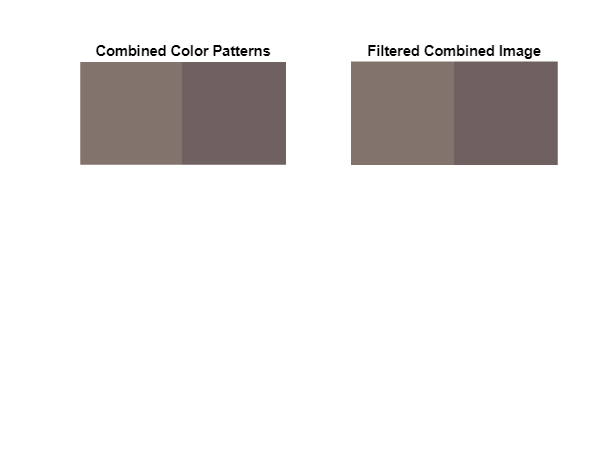


% Define the RGB values for Color Pattern I and II
ColorPatternI = [130, 115, 108];
ColorPatternII = [110, 97, 96];

r = zeros(100,200);
g = r;
b = r;
r(:,1:100) = ColorPatternI(1);
g(:,1:100) = ColorPatternI(2);
b(:,1:100) = ColorPatternI(3);
r(:,100:end) = ColorPatternII(1);
g(:,100:end) = ColorPatternII(2);
b(:,100:end) = ColorPatternII(3);
col1 = cat(3,r,g,b);


% Create Color Pattern I and II images
color_pattern_I = cat(3, 130, 115, 108)/255;
color_pattern_II = cat(3, 110, 97, 96)/255;
combined_image = cat(2, color_pattern_I, color_pattern_II);






figure;
subplot(2, 2, 1);
imshow(col1/255);
title('Combined Color Patterns');
 
subplot(2, 2, 2);
imshow(combined_image);
title('Filtered Combined Image');

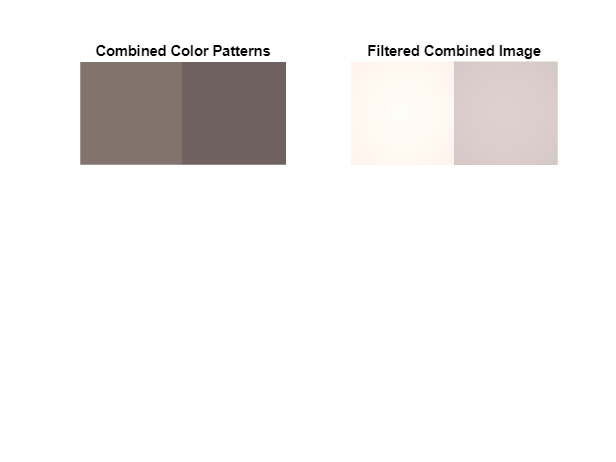

% Define the sigma values for Gaussian kernels
sigma1 = 10;


% Define the size of the kernel (you can adjust as needed)
kernelSize = 5;  % For example, a 5x5 kernel

% Create Gaussian kernels for sigma1 and sigma2
[x, y] = meshgrid(-50:50, -50:50);
gaussianKernel1 = exp(-(x.^2 + y.^2)/(2*sigma1^2) / (2 *pi* sigma1^2));

filter_size1 =  20;

% Normalize the kernels to sum to 1
Gs = gaussianKernel1; %/ sum(gaussianKernel1(:));
DoG = fspecial('gaussian', filter_size1, 1) - fspecial('gaussian', filter_size1, 10);

edge_image1 = conv2(col1(:,:,1),DoG,'same');
edge_image2 = conv2(col1(:,:,2),DoG,'same');
edge_image3 = conv2(col1(:,:,3),DoG,'same');
ed = cat(3,edge_image1,edge_image2,edge_image3);
% Calculate transformed components for Color Pattern I
R1 = ColorPatternI(1);
G1 = ColorPatternI(2);
B1 = ColorPatternI(3);
h1I = DoG(1) * R1 + Gs * (2 * R1 + G1 - B1);
h2I = DoG(2) * G1 + Gs * (R1 + 2 * G1 - B1);
h3I = DoG(3) * B1 + Gs * (R1 + G1);

newcol1 = cat(3,h1I,h2I,h3I);


% Calculate transformed components for Color Pattern II
R2 = ColorPatternII(1);
G2 = ColorPatternII(2);
B2 = ColorPatternII(3);
h1II = DoG(1) * R2 + Gs * (2 * R2 + G2 - B2);
h2II = DoG(2) * G2 + Gs * (R2 + 2 * G2 - B2);
h3II = DoG(3) * B2 + Gs * (R2 + G2);
newcol2 = cat(3,h1II,h2II,h3II);

comb2 = cat(2, newcol1,newcol2);


figure;
subplot(2, 2, 1);
imshow(col1/255)
title('Combined Color Patterns');
 
subplot(2, 2, 2);
imshow(uint8(comb2))
title('Filtered Combined Image');


i = 50;
j = 50;
d1 = norm(ColorPatternI-ColorPatternII)

d1 = 29.4618

d = sqrt((newcol1(i,j,1)-newcol2(i,j,1))^2+(newcol1(i,j,2)-newcol2(i,j,2))^2 + (newcol1(i,j,3)-newcol2(i,j,3))^2)

d = 74.0904

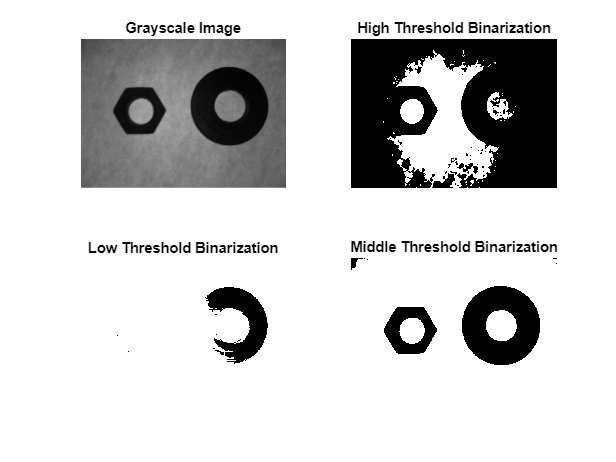

% Read the input image
image = imread('nut_and_shell.png');

% Convert the image to grayscale
gray_image = rgb2gray(image);


% Determine thresholds based on the histogram
% In this example, we'll use three different thresholds:
% - Overestimate: High threshold
% - Underestimate: Low threshold
% - In-between: Middle threshold
high_threshold = 125;   % Adjust as needed (overestimate)
low_threshold = 10;    % Adjust as needed (underestimate)
middle_threshold = 75; % Adjust as needed (in-between)

% Binarize the image using the thresholds
binary_high = gray_image > high_threshold;
binary_low = gray_image > low_threshold;
binary_middle = gray_image > middle_threshold;

% Display the original grayscale image and the three binarized images
figure;

subplot(2, 2, 1);
imshow(gray_image);
title('Grayscale Image');

subplot(2, 2, 2);
imshow(binary_high);
title('High Threshold Binarization');

subplot(2, 2, 3);
imshow(binary_low);
title('Low Threshold Binarization');

subplot(2, 2, 4);
imshow(binary_middle);
title('Middle Threshold Binarization');



% Label connected components in the binary image
labeled_image = bwlabel(binary_middle);

% Calculate region properties for each labeled object
stats = regionprops(labeled_image, 'Area', 'Centroid');

% Initialize variables to store the areas and centroids
nut_area = 0;
nut_centroid = [0, 0];
shell_area = 0;
shell_centroid = [0, 0];

% Loop through the region properties
for i = 1:numel(stats)
    % Check the area to distinguish between the nut and shell
    if stats(i).Area > 10400 % You can adjust this area threshold as needed
        % The object with a larger area is the shell
        shell_area = stats(i).Area;
        shell_centroid = stats(i).Centroid;
    else
        % The object with a smaller area is the nut
        nut_area = stats(i).Area;
        nut_centroid = stats(i).Centroid;
    end
end

% Display the results
disp(['Nut Area: ', num2str(nut_area)]);

Nut Area: 10331


disp(['Nut Centroid: ', num2str(nut_centroid)]);

Nut Centroid: 272.1537      324.1978


disp(['Shell Area: ', num2str(shell_area)]);

Shell Area: 15072


disp(['Shell Centroid: ', num2str(shell_centroid)]);

Shell Centroid: 668.0594      301.2657


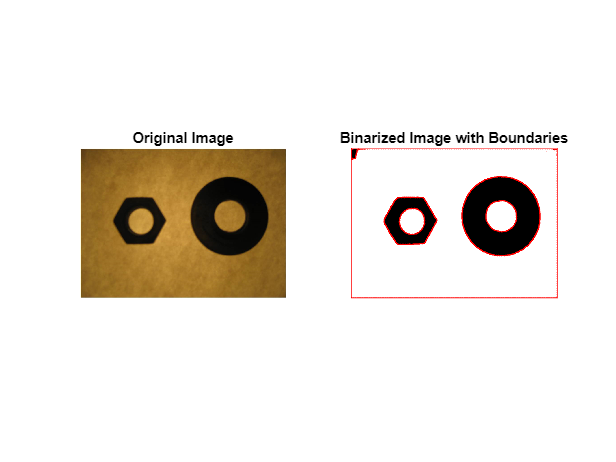


% Find and plot the boundaries of the nut and shell
boundaries = bwboundaries(binary_middle);

% Initialize a figure to display the results
figure;

% Display the original image
subplot(1, 2, 1);
imshow(image);
title('Original Image');

% Display the binary image with boundaries
subplot(1, 2, 2);
imshow(binary_middle);
title('Binarized Image with Boundaries');

% Plot the boundaries on the binary image
hold on;
for k = 1:length(boundaries)
    boundary = boundaries{k};
    plot(boundary(:, 2), boundary(:, 1), 'r', 'LineWidth', 1);
end
hold off;

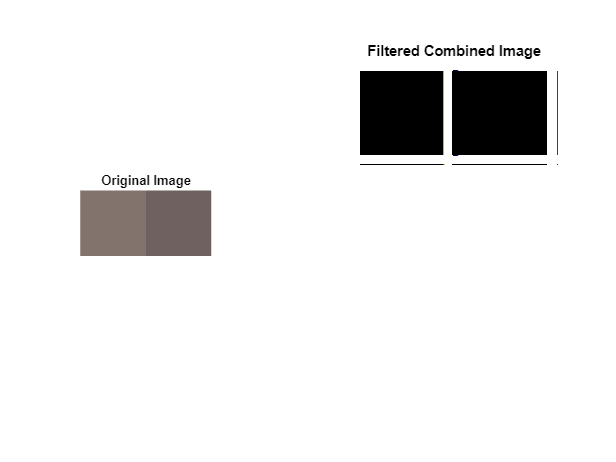

ColorPatternI = [130, 115, 108];
ColorPatternII = [110, 97, 96];
R1 = ColorPatternI(1);
G1 = ColorPatternI(2);
B1 = ColorPatternI(3);
R2 = ColorPatternII(1);
G2 = ColorPatternII(2);
B2 = ColorPatternII(3);

% Define the RGB values for the two squares
color1 = [130, 115, 108];
color2 = [110, 97, 96];

% Create a 100x100 square filled with color1
square1 = repmat(reshape(color1, [1, 1, 3]), [100, 100, 1]);

% Create a 100x100 square filled with color2
square2 = repmat(reshape(color2, [1, 1, 3]), [100, 100, 1]);

% Create an empty 100x200 image
image = zeros(100, 200, 3);

% Place the two squares side by side to form a 100x200 image
image(:, 1:100, :) = square1;
image(:, 101:200, :) = square2;

% Display the resulting image
% imshow(uint8(image));  % Uncomment this line if you want to display the image

% Define Gaussian kernel parameters
sigma1 = 1;
sigma2 = 10;
kernelSize = 5;  % Adjust the kernel size as needed

% Create Gaussian kernels
Gs = fspecial('gaussian', kernelSize, sigma2);
DoG = fspecial('gaussian', kernelSize, sigma1) - fspecial('gaussian', kernelSize, sigma2);
% Apply Gaussian filters to the image
blurredImage1 = imfilter(image, DoG, 'conv', 'replicate');


h1I = DoG(1) * R1 + Gs * (2 * R1 + G1 - B1);
h2I = DoG(2) * G1 + Gs * (R1 + 2 * G1 - B1);
h3I = DoG(3) * B1 + Gs * (R1 + G1);

newcol1 = cat(3,h1I,h2I,h3I);


% Calculate transformed components for Color Pattern II
R2 = ColorPatternII(1);
G2 = ColorPatternII(2);
B2 = ColorPatternII(3);
h1II = DoG(1) * R2 + Gs * (2 * R2 + G2 - B2);
h2II = DoG(2) * G2 + Gs * (R2 + 2 * G2 - B2);
h3II = DoG(3) * B2 + Gs * (R2 + G2);
newcol2 = cat(3,h1II,h2II,h3II);

comb3 = cat(2, newcol1,newcol2);


% Display the original image and the DoG image side by side
subplot(1, 3, 1);
imshow(uint8(image));
title('Original Image');

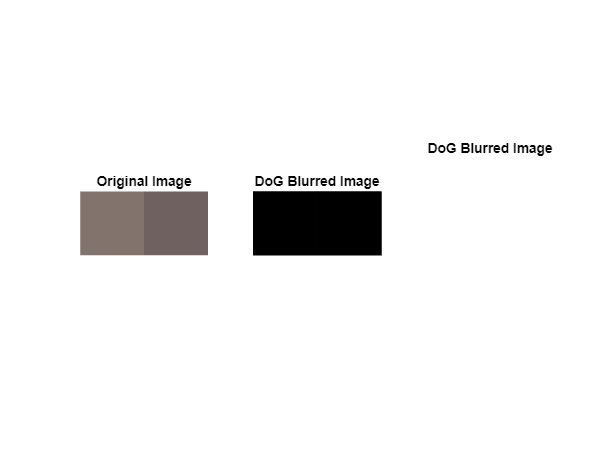


subplot(1, 3, 2);
imshow(uint8(blurredImage1));
title('DoG Blurred Image');

subplot(1, 3, 3);
imshow(newcol2);
title('DoG Blurred Image');